# Seminar 12 - Monte Carlo implementations

**Authors:** Ing. David Vošahlík, prof. Ing. Vladimír Havlena, CSc.

## Introduction

Pseudorandom generators and Kalman particle filter will be studied in this seminar.

## Pseudorandom generators

Many of pseudorandom generators are based on having the uniform distribution and then transforming it into the desired one. 

### Uniform distribution

Your first task will be to implement pseudorandom uniform distribution generator by cungurence method

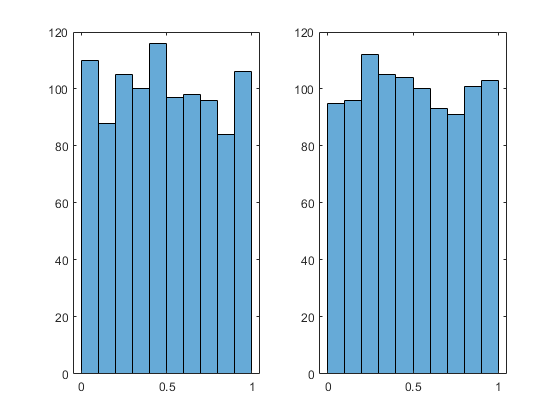

% Congruence method (Linear congruential generator)
% x_n+1 = (a*x_n+c) mod m

N = 1000;
m = 2^32;       % modulus       0 < m
a = 69069;      % multiplier    0 < a < m
% a = 22695477;
c = 1;          % increment     0 < c < m
x0 = 500;       % seed          0 <= x0 < m

x = zeros(1,N);
x(1) = mod(a*x0+c,m);
for i = 2:N
    x(i) = mod(a*x(i-1)+c,m);
end

u = m^(-1).*x;

close all
figure;
subplot(1,2,1)
histogram(u)

% Matlab functions for comparison
subplot(1,2,2)
histogram(rand(1,N)) % Uniformly distributed pseudorandom numbers. 

### Transformation by inverse of cumulative distribution function *F*

One of the approaches is via the inverse of cumulative distribution function *F*. The steps are:

- Get sample $\left.u~U\left(0,1\right)\in \;<0,1\right)$

- $x=F^{-1} \left(u\right)$ has p.d.f. $f\left(x\right)$

Your task will be to implement this approach for $f\left(x\right)$ is normal p.d.f.

Hint: 

- *Use ****norminv**** function*

- *Use the samples computed in previous task*

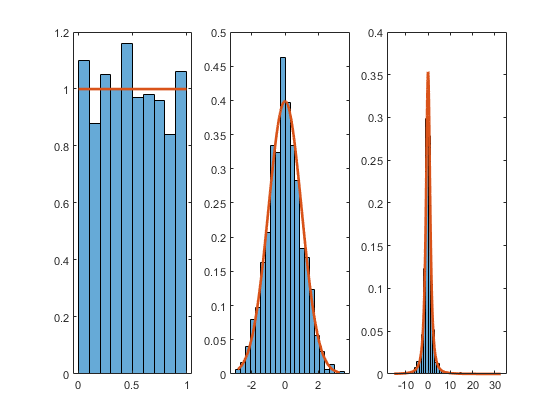

u_normal = norminv(u);
u_student = tinv(u,2);

figure;
subplot(1,3,1)
histogram(u,'Normalization','pdf')
hold on;
plot(u, unifpdf(u), 'LineWidth', 2);
subplot(1,3,2)
histogram(u_normal,'Normalization','pdf')
hold on;
plot(sort(u_normal), normpdf(sort(u_normal)), 'LineWidth', 2);
subplot(1,3,3)
histogram(u_student,'Normalization','pdf')
hold on;
plot(sort(u_student), tpdf(sort(u_student), 2), 'LineWidth', 2);

### Resampling methods

Another approach are the resampling methods. One of them is the direct sampling method. The steps are:

- Samples $x_{i\;} ~g\left(x\right)$ are available. It can be any distribution. This can be e.g. $x_i ~U\left(-1\ldotp 5,1\ldotp 5\right)$

- Determine $M$ such that $\frac{f\left(x\right)}{g\left(x\right)}<M$. In our example $f\left(x\right)={\frac{1}{2\ldotp 1}e}^{-\frac{x^2 }{2}}$ resulting in $M=1\ldotp 4$.

Then the algorithm is:

- Get sample $x~g\left(x\right)$

- Get sample $u~U\left(0,1\right)$

- if $u\le \frac{f\left(x\right)}{M\;g\left(x\right)}$, accept the sample - this one is from $f\left(x\right)$ p.d.f. Otherwise go with step 1

Your task will be to implement this algorithm for the example mentioned in the description.

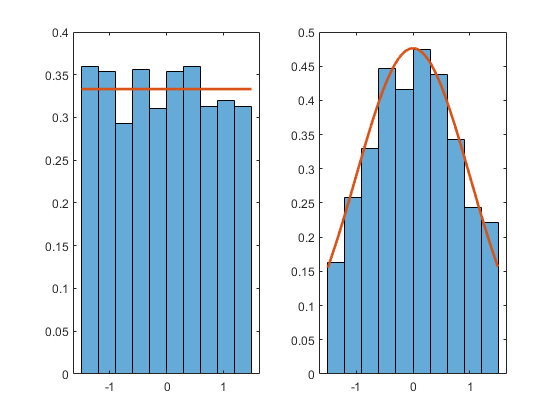

% classical sampling method which allows one to sample from a distribution 
% which is difficult or impossible to simulate by an inverse transformation

N = 1000;

f = @(x)1/2.1*exp((-x.^2)/2);  % p.d.f. we want to sample from 
g = @(x)1/3;                      % p.d.f. another uniform 
M = 1.4;
 
y = [];
x = rand(1,N)*3-1.5;            % generate samples from g(x)
for i = 1:N
    u = rand;                   % generate another uniformly dist. samples
    if u <= f(x(i))/(M*g(x(i))) % accept/reject condition
        y = [y x(i)];           % accepted
    end 
end
 
figure;
subplot(1,2,1)
histogram(x,'Normalization','pdf')
hold on;
plot(sort(x), 1/3*ones(size(x)), 'LineWidth', 2);
subplot(1,2,2)
histogram(y,'Normalization','pdf')
hold on;
plot(sort(y), f(sort(y)), 'LineWidth', 2);

## Numerical integration

With Monte Carlo also numerical integration implementation is available. This is based on the empirical p.d.f. and Dirac "shifting property". 


$$E\left\lbrace f\right\rbrace =\int f\left(\theta \right)p\left(\theta \right)d\theta =\frac{1}{N}\sum_{i\;=1}^N \int f\left(\theta \right)\delta \left(\theta -\theta_i \right)d\theta =\frac{1}{N}\sum_{i\;=\;1}^N f\left(\theta_i \right)$$


Your task will be to implement such integration for $\pi$ estimation. It is based on known integral equation


$$\pi =4\;\int_0^1 \sqrt{1-x^2 \;}p\left(x\right)\textrm{dx}$$


Hint: *Use *$x_i ~U\left(0,1\right)$

% Estimate pi value

N = 10000;
x = rand(1,N);

pi_est = 0;
for i = 1:N
    pi_est = pi_est + sqrt(1-x(i)^2);
end
pi_est = 4/N*pi_est;

% diference between pi and estimated pi by MC
diff = pi - pi_est

diff = 0.0056

## Kalman particle filter

For quick reminder of the particle filter idea see the [video](http://youtu.be/aUkBa1zMKv4) by Andreas Svensson. It explains the main points behind it. Try to run the PF function that is attached to this script (standalone m file). This is the function created by Andreas Svensson to support his video. You can chceck all the detailed numerical implementations there.